## Parámetros

syms q1(t) q2(t) t theta
syms m1 l1 lc1 I1 m2 l2 lc2 I2 g

## Cinematica directa y diferencial

%xy2 = @(q1,q2) [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)];
%xy2(0,pi/2)
%v1 = @(q1,vq1) [-lc1*sin(q1); lc1*cos(q1)].*vq1;
%v1(pi/2,1)
%v2 = @(q1,q2,vq1,vq2) [-l1*sin(q1)-lc2*sin(q1+q2) -lc2*sin(q1+q2); l1*cos(q1)+lc2*cos(q1+q2) lc2*cos(q1+q2)]*[vq1;vq2];
%v2(0,0,1,1)
xy1 = [lc1*cos(q1); lc1*sin(q1)]

$$xy1(t) = \left(\begin{array}{c} {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ {\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right) \end{array}\right)$$

xy2 = [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)]

$$xy2(t) = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

cdE = [l1*cos(q1)+l2*cos(q1+q2); l1*sin(q1)+l2*sin(q1+q2)]

$$cdE(t) = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

v1 = diff(xy1,t)

$$v1(t) = \left(\begin{array}{c} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

v2 = diff(xy2,t)

$$v2(t) = \left(\begin{array}{c} -{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)-l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ {\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

## Energía Cinética

K = 1/2*(m1*transpose(v1)*v1 + I1*diff(q1,t)^2 + m2*transpose(v2)*v2 + I2*(diff(q1,t)+diff(q2,t))^2)

$$K(t) = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{2}\,{\sigma_{1}}^{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

% Compute simplified symbolic expression
K

$$K(t) = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{2}\,{\sigma_{1}}^{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

simplifiedExpr = simplify(K)

$$simplifiedExpr(t) = \begin{array}{l} \frac{I_{1}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{2}}{2}+I_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{{l_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\sigma_{2}}{2}+{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2} \end{array}$$

## Energía Potencial

U = m1*g*lc1*sin(q1) + m2*g*(l1*sin(q1)+lc2*sin(q1+q2))

$$U(t) = g\,m_{2}\,\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)$$

## Parámetros

% Eslabón 1
IRod = 0.874+0.012*95.404^2;
mRod = 12;
IBrid = 0.369+0.01*95.404^2;
mBrid = 10;
ITor = (0.002+0.001*8^2)*4+0.004*95.404^2;
mTor = 4;
d2 = 187-95.404;
ICar = (0.874+4.668)+(0.012+0.017)*(d2)^2;
mCar = 17+12;
ITorL = (0.003+0.002*17^2)*4+0.008*(d2)^2;
mTorL = 8;
IEje = 0.189+0.024*(d2)^2;
mEje = 24;
IPol = 0.201+0.006*(d2)^2;
mPol = 6;

I1 = (345.242 + IRod + IBrid + ICar + ITor + ITorL + IEje + IPol)/1E6 %Nms^2

I1 = 0.0012

m1 = (70 + mRod + mBrid + mCar + mTor + mTorL + mEje + mPol)/1E3 %kg

m1 = 0.1630

lc1 = (95.404+(-95.404*mRod - 95.404*mBrid - 95.404*mTor + d2*mCar + d2*mTorL + d2*mEje + d2*mPol)/(1E3*m1))/1E3 %m

lc1 = 0.1178

l1 = 0.187 %m

l1 = 0.1870


% Eslabón 2
d3 = 74.450;
mBrid8 = 5;
IBrid8 = 0.117 + mBrid8/1000*d3^2;
mTorB = 4;
ItorB = (0.002+0.001*12^2)+mTorB/1000*d3^2;
mServ = 15;
Iserv = 1.317 + mServ/1000*(137-d3+13.8)^2;
mSopM = 5;
IsopM = 0.485 + mSopM/1000*(181-74.450)^2;
mMarc = 14.8;
Imarc = 0.535 + mMarc/1000*(181-74.450)^2;

I2 = (194.707 + IBrid8 + ItorB + Iserv + IsopM + Imarc)/1E6 %Nms^2

I2 = 5.5942e-04

m2 = (60 + mBrid8 + mTorB + mServ + mSopM + mMarc)/1E3 %kg

m2 = 0.1038

lc2 = (d3 + (-d3*mBrid8 - d3*mTorB + (137-d3+13.8)*mServ + (181-74.450)*mSopM +  (181-74.450)*mMarc)/(1E3*m2))/1E3 %m

lc2 = 0.0994

l2 = 0.181 %m

l2 = 0.1810


g = 9.81 %m/s^2

g = 9.8100

### Matriz de inercia

cm11_1 = I1 + I2 + m1*lc1^2 + m2*l1^2 + m2*lc2^2

cm11_1 = 0.0086

cm11_2 = 2*l1*lc2*m2

cm11_2 = 0.0039

cm12_1 = I2 + lc2^2*m2

cm12_1 = 0.0016

cm12_2 = l1*lc2*m2

cm12_2 = 0.0019

cm22 = I2+m2*lc2^2

cm22 = 0.0016


M = @(q2) [cm11_1+cm11_2*cos(q2) cm12_1+cm12_2*cos(q2)
    cm12_1+cm12_2*cos(q2) cm22]

M = function_handle with value:
    @(q2)[cm11_1+cm11_2*cos(q2),cm12_1+cm12_2*cos(q2);cm12_1+cm12_2*cos(q2),cm22]


### Vector de pares gravitacionales

G = [diff(U,q1); diff(U,q2)]

$$G(t) = \left(\begin{array}{c} g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ g\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$


G = @(q1,q2) [g*m2*l1*cos(q1)+g*m2*lc2*cos(q1+q2)+g*lc1*m1*cos(q1)
    g*lc2*m2*cos(q1+q2)]

G = function_handle with value:
    @(q1,q2)[g*m2*l1*cos(q1)+g*m2*lc2*cos(q1+q2)+g*lc1*m1*cos(q1);g*lc2*m2*cos(q1+q2)]


### Matriz de fuerzas centrípetas y de Coriolis

M_sym = [cm11_1+cm22*cos(q2) cm12_1+cm12_2*cos(q2)
    cm12_1+cm12_2*cos(q2) cm22]

$$M\_sym(t) = \left(\begin{array}{cc} \frac{3652508441001787\,\cos\left(q_{2}\left(t\right)\right)}{2305843009213693952}+\frac{4975368836259751}{576460752303423488} & \frac{8893606971746701\,\cos\left(q_{2}\left(t\right)\right)}{4611686018427387904}+\frac{3652508441001787}{2305843009213693952}\\ \frac{8893606971746701\,\cos\left(q_{2}\left(t\right)\right)}{4611686018427387904}+\frac{3652508441001787}{2305843009213693952} & \frac{3652508441001787}{2305843009213693952} \end{array}\right)$$

Mdot = diff(M_sym,t)

$$Mdot(t) = \left(\begin{array}{cc} -\frac{3652508441001787\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & -\frac{8893606971746701\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904}\\ -\frac{8893606971746701\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904} & 0 \end{array}\right)$$

Mdote = Mdot(t)

$$Mdote = \left(\begin{array}{cc} -\frac{3652508441001787\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & -\frac{8893606971746701\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904}\\ -\frac{8893606971746701\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904} & 0 \end{array}\right)$$

C_sym = [Mdote(1,1)/2 Mdote(1,2)+Mdote(2,1)
    Mdote(1,2)+Mdote(2,1) Mdote(2,2)/2]

$$C\_sym = \left(\begin{array}{cc} -\frac{3652508441001787\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904} & -\frac{8893606971746701\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952}\\ -\frac{8893606971746701\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & 0 \end{array}\right)$$

C = @(q2, vq2) [ (1/2*m2*lc2^2+I2)*sin(q2)*vq2  -2*l1*lc2*m2*sin(q2)*vq2
    -2*l1*lc2*m2*sin(q2)*vq2 0]

C = function_handle with value:
    @(q2,vq2)[(1/2*m2*lc2^2+I2)*sin(q2)*vq2,-2*l1*lc2*m2*sin(q2)*vq2;-2*l1*lc2*m2*sin(q2)*vq2,0]


## Cinemática Inversa

ci_q2 = @(x,y) acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))

ci_q2 = function_handle with value:
    @(x,y)acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))


ci_q1 = @(x,y,q2) atan2(y,x) - atan2(l2.*sin(q2),l1+l2.*cos(q2))

ci_q1 = function_handle with value:
    @(x,y,q2)atan2(y,x)-atan2(l2.*sin(q2),l1+l2.*cos(q2))


# Torque

tau = @(q1, q2, vq1, vq2, aq1, aq2) M(q2)*[aq1; aq2] + C(q2,vq2)*[vq1; vq2] + G(q1,q2)

tau = function_handle with value:
    @(q1,q2,vq1,vq2,aq1,aq2)M(q2)*[aq1;aq2]+C(q2,vq2)*[vq1;vq2]+G(q1,q2)


syms theta
n = 1000

n = 1000

a = 3.2604;
k = 3;
b = 1;
r = a*k+a*cos(4*theta+b*pi);
x = (r.*cos(theta) + 20)/100;
y = (r.*sin(theta) + 9)/100;

%integrand = @(th) a*sqrt((k+cos(4*th+b*pi)).^2+16*(sin(4*th+b*pi).^2));
%Length = @(tho,thf) integral(integrand,tho,thf);
V_req = 10 %cm/s

V_req = 10


t = zeros(1,n);
step = 2*pi/(n-1) %rad

step = 0.0063

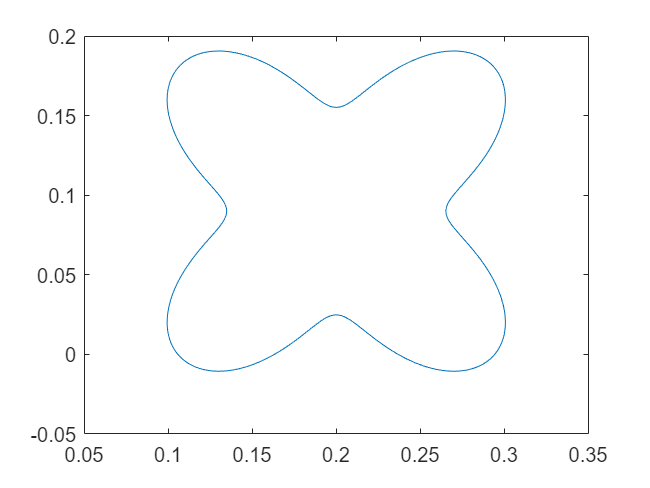

% for i = 1:n
%     if i == 1
%        t(i) = 0 + Length((i-1)*2*pi/n,(i-1)*2*pi/n+2*pi/n);
%    else
%        t(i) = t(i-1) + Length((i-1)*2*pi/n,(i-1)*2*pi/n+2*pi/n);
%    end
%end

%tt = 0:t(n)/(n-1):t(n)
theta = 0:step:2*pi;
%ttheta = spline(t,theta,tt);
%plot(tt,ttheta)
x = double(subs(x));
y = double(subs(y));
plot(x,y);

t_total = 10

t_total = 10

t = linspace(0,2*t_total,2*n)

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3002    0.3102    0.3202    0.3302    0.3402    0.3502    0.3602    0.3702    0.3802    0.3902    0.4002    0.4102    0.4202    0.4302    0.4402    0.4502    0.4602    0.4702    0.4802    0.4902


q2 = [ci_q2(x,y) ci_q2(x,y)]

q2 =     1.4120    1.4108    1.4095    1.4080    1.4064    1.4046    1.4027    1.4006    1.3983    1.3959    1.3934    1.3907    1.3878    1.3848    1.3816    1.3783    1.3748    1.3712    1.3674    1.3634    1.3593    1.3551    1.3506    1.3461    1.3414    1.3365    1.3315    1.3264    1.3210    1.3156    1.3100    1.3043    1.2984    1.2924    1.2862    1.2799    1.2735    1.2670    1.2603    1.2535    1.2466    1.2395    1.2323    1.2250    1.2176    1.2101    1.2025    1.1948    1.1869    1.1790


vq2 = [0 diff(q2)./diff(t)]

vq2 =          0   -0.1178   -0.1328   -0.1478   -0.1629   -0.1782   -0.1934   -0.2088   -0.2242   -0.2396   -0.2551   -0.2706   -0.2861   -0.3017   -0.3172   -0.3328   -0.3483   -0.3638   -0.3792   -0.3947   -0.4100   -0.4253   -0.4406   -0.4557   -0.4708   -0.4858   -0.5007   -0.5154   -0.5301   -0.5446   -0.5589   -0.5731   -0.5872   -0.6011   -0.6148   -0.6283   -0.6416   -0.6547   -0.6677   -0.6803   -0.6928   -0.7050   -0.7170   -0.7287   -0.7401   -0.7512   -0.7621   -0.7726   -0.7829   -0.7928


aq2 = [0 diff(vq2)./diff(t)]

aq2 =          0  -11.7768   -1.4940   -1.5036   -1.5124   -1.5203   -1.5274   -1.5337   -1.5391   -1.5436   -1.5473   -1.5501   -1.5521   -1.5532   -1.5534   -1.5527   -1.5511   -1.5487   -1.5453   -1.5411   -1.5360   -1.5300   -1.5231   -1.5153   -1.5066   -1.4970   -1.4865   -1.4752   -1.4629   -1.4497   -1.4356   -1.4206   -1.4047   -1.3879   -1.3701   -1.3515   -1.3320   -1.3115   -1.2901   -1.2678   -1.2445   -1.2203   -1.1952   -1.1691   -1.1420   -1.1140   -1.0850   -1.0550   -1.0240   -0.9920


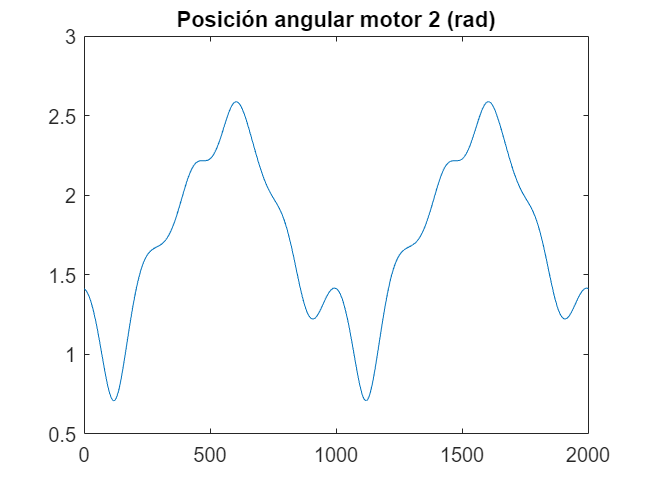

plot(q2);
title('Posición angular motor 2 (rad)')

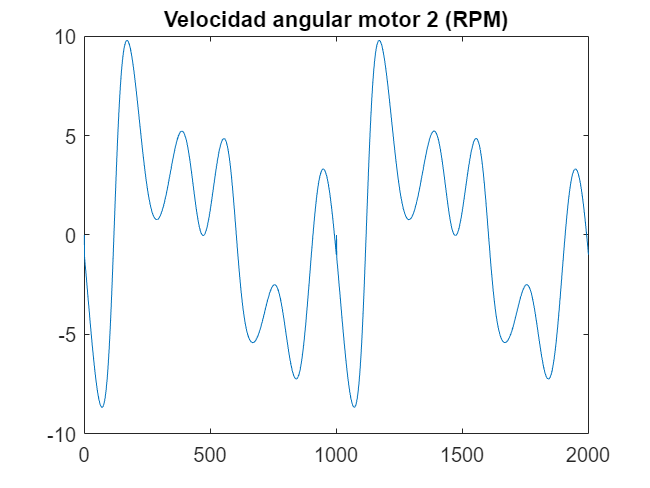

plot(vq2*30/pi);
title('Velocidad angular motor 2 (RPM)')

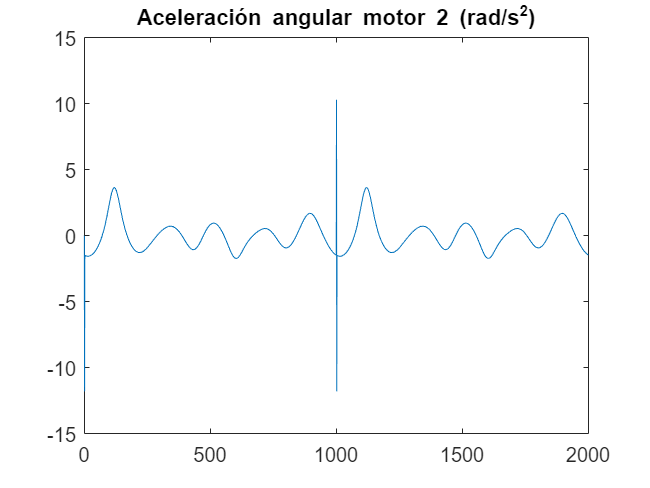

plot(aq2);
title('Aceleración angular motor 2 (rad/s^2)')


q2aux = ci_q2(x,y)

q2aux =     1.4120    1.4108    1.4095    1.4080    1.4064    1.4046    1.4027    1.4006    1.3983    1.3959    1.3934    1.3907    1.3878    1.3848    1.3816    1.3783    1.3748    1.3712    1.3674    1.3634    1.3593    1.3551    1.3506    1.3461    1.3414    1.3365    1.3315    1.3264    1.3210    1.3156    1.3100    1.3043    1.2984    1.2924    1.2862    1.2799    1.2735    1.2670    1.2603    1.2535    1.2466    1.2395    1.2323    1.2250    1.2176    1.2101    1.2025    1.1948    1.1869    1.1790


q1 = [ci_q1(x,y,q2aux) ci_q1(x,y,q2aux)]

q1 =    -0.3649   -0.3630   -0.3610   -0.3589   -0.3568   -0.3547   -0.3524   -0.3502   -0.3478   -0.3454   -0.3429   -0.3404   -0.3378   -0.3351   -0.3324   -0.3296   -0.3267   -0.3238   -0.3208   -0.3177   -0.3145   -0.3113   -0.3079   -0.3045   -0.3011   -0.2975   -0.2939   -0.2902   -0.2864   -0.2825   -0.2785   -0.2745   -0.2704   -0.2662   -0.2619   -0.2576   -0.2531   -0.2486   -0.2440   -0.2393   -0.2346   -0.2297   -0.2248   -0.2198   -0.2147   -0.2096   -0.2044   -0.1991   -0.1937   -0.1883


vq1 = [0 diff(q1)./diff(t)]

vq1 =          0    0.1948    0.1999    0.2053    0.2107    0.2164    0.2221    0.2281    0.2341    0.2403    0.2467    0.2531    0.2597    0.2665    0.2733    0.2803    0.2873    0.2945    0.3018    0.3092    0.3167    0.3242    0.3319    0.3396    0.3474    0.3552    0.3631    0.3711    0.3791    0.3871    0.3952    0.4033    0.4113    0.4194    0.4275    0.4356    0.4437    0.4517    0.4597    0.4677    0.4756    0.4835    0.4913    0.4990    0.5067    0.5142    0.5217    0.5290    0.5362    0.5433


aq1 = [0 diff(vq1)./diff(t)]

aq1 =          0   19.4678    0.5166    0.5320    0.5473    0.5623    0.5771    0.5916    0.6059    0.6198    0.6335    0.6468    0.6597    0.6723    0.6844    0.6961    0.7073    0.7181    0.7283    0.7381    0.7472    0.7559    0.7639    0.7714    0.7782    0.7844    0.7899    0.7948    0.7990    0.8025    0.8053    0.8074    0.8087    0.8093    0.8091    0.8082    0.8065    0.8040    0.8007    0.7966    0.7917    0.7860    0.7794    0.7721    0.7638    0.7548    0.7449    0.7342    0.7226    0.7102


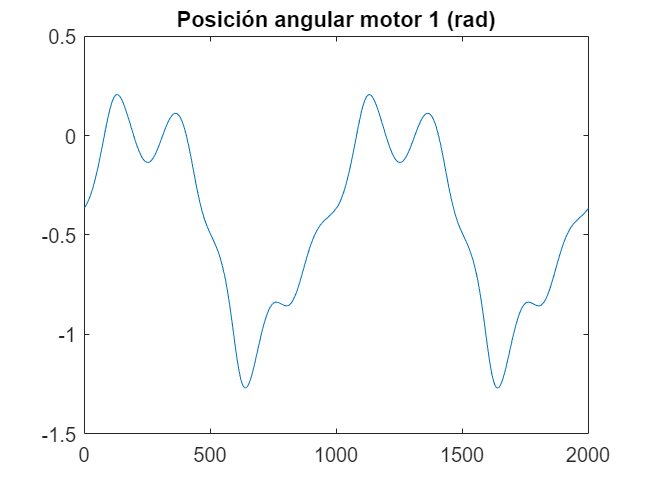

plot(q1);
title('Posición angular motor 1 (rad)')

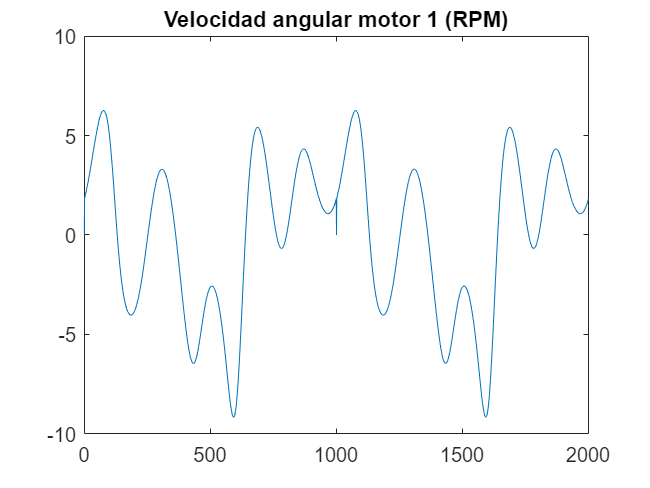

plot(vq1*30/pi);
title('Velocidad angular motor 1 (RPM)')

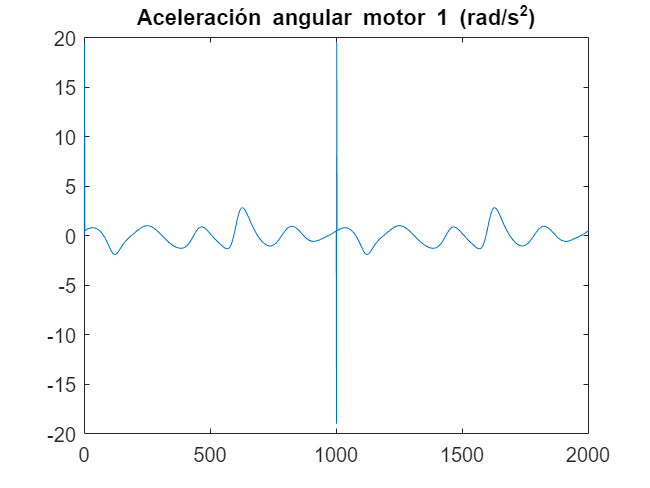

plot(aq1);
title('Aceleración angular motor 1 (rad/s^2)')


TAU = zeros(2,2*n)

TAU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


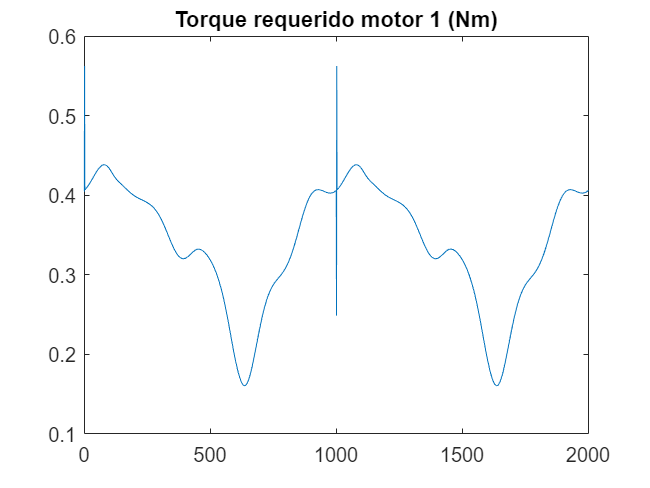

for i = 1:2*n
    TAU(:,i) = tau(q1(i),q2(i),vq1(i),vq2(i),aq1(i),aq2(i));
end
plot(TAU(1,:))
title('Torque requerido motor 1 (Nm)')

TRMS1 = rms(TAU(1,:))

TRMS1 = 0.3475

Tmax1 = max(TAU(1,:))

Tmax1 = 0.5623

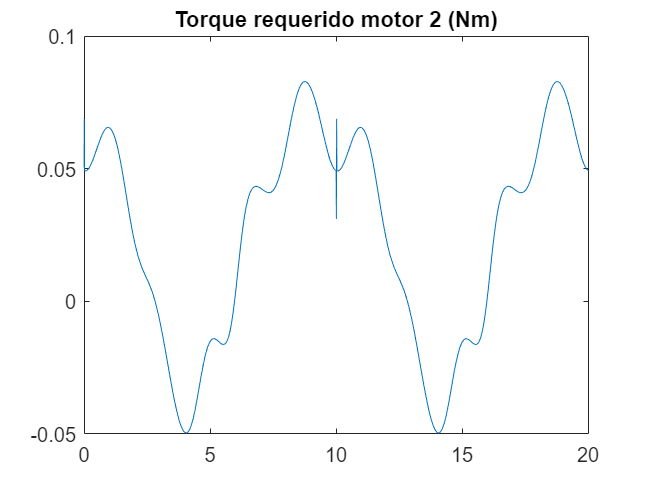


plot(t,TAU(2,:))
title('Torque requerido motor 2 (Nm)')

TRMS2 = rms(TAU(2,:))

TRMS2 = 0.0467

Tmax2 = max(TAU(2,:))

Tmax2 = 0.0828


pos1 = [t; q1]'

pos1 =          0   -0.3649
    0.0100   -0.3630
    0.0200   -0.3610
    0.0300   -0.3589
    0.0400   -0.3568
    0.0500   -0.3547
    0.0600   -0.3524
    0.0700   -0.3502
    0.0800   -0.3478
    0.0900   -0.3454


pos2 = [t; q2]'

pos2 =          0    1.4120
    0.0100    1.4108
    0.0200    1.4095
    0.0300    1.4080
    0.0400    1.4064
    0.0500    1.4046
    0.0600    1.4027
    0.0700    1.4006
    0.0800    1.3983
    0.0900    1.3959
